% Run ptempest
Expierments.expierment_1.S0 = 100;
Expierments.expierment_1.E0 = 10;
key_struct= run_ptempest(Expierments,100);

'Fits' location already exists and will continue with the existing folder 
Building with 'Xcode with Clang'.
xcrun: error: SDK "macosx10.15.1" cannot be located

xcrun: error: SDK "macosx10.15.1" cannot be located

xcrun: error: SDK "macosx10.15.1" cannot be located

xcrun: error: SDK "macosx10.15.1" cannot be located

xcrun: error: SDK "macosx10.15.1" cannot be located

MEX completed successfully.
------------------------------------------------------
Parallel Tempering for CLP_HA
------------------------------------------------------


cfg = struct with fields:
                              jobname: 'pt'
                              shuffle: 1
                             parallel: 0
                              maxlabs: 1
                              nchains: 4
                               nswaps: 1000
                               nsteps: 25
              display_status_interval: 10
               save_progress_interval: 100
               adapt_relstep_interval: 100
                   adapt_relstep_rate: 0.2000
              optimal_step_acceptance: 0.2400
                  adapt_beta_interval: 250
                      adapt_beta_rate: 0.0400
              optimal_swap_acceptance: 0.2400
                           adapt_last: 2900
                  min_adaption_factor: 0.8000
                  max_adaption_factor: 1.2500
                      energy_init_max: 1000
                       max_init_steps: 500
                             max_beta: 1
                            beta_init: 0.6660
               

------------------------------------------------------
Initializing random number streams [ method=mrg32k3a, nstreams=1, shuffle=1 ]
------------------------------------------------------
Looking for good initial parameter set . . .
  . . . 5 attempts (energy curr=2924.94, best=2922.87)
  . . . 10 attempts (energy curr=2924.94, best=2922.87)
  . . . 15 attempts (energy curr=2924.94, best=2409.42)
  . . . 20 attempts (energy curr=4732.7, best=2409.42)
 . . . energy at initial starting point is 77.244
------------------------------------------------------
Initializing chains...
chain 1 . . .  initial energy = 130.825
chain 2 . . .  initial energy = 38.5603
chain 3 . . .  initial energy = 926.309
chain 4 . . .  initial energy = 935.799
------------------------------------------------------
Ready to go!
------------------------------------------------------
  total swaps = 1000
------------------------------------------------------
  chain 1: T=1.0000 relstep=0.01     currE=131     
  chai

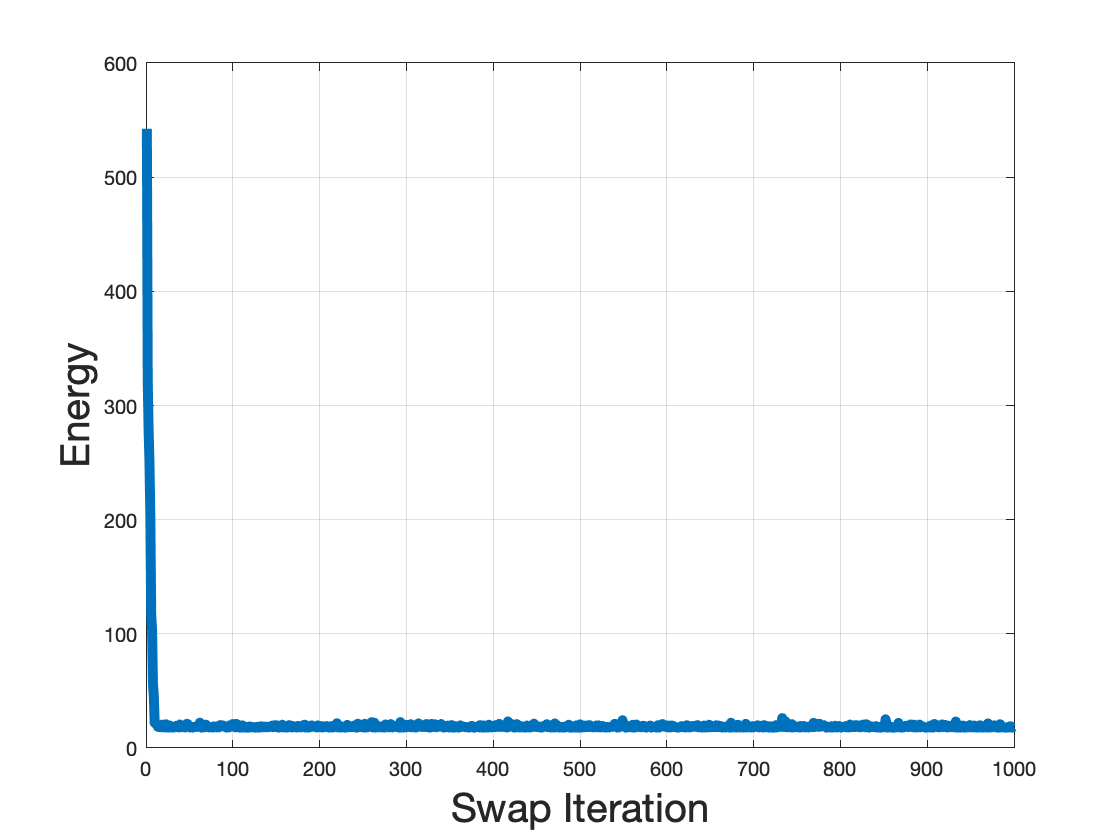

% Plot energy chains
x=plotting_tool(key_struct.output_location);
%x.plot_all_energy_chains;
x.plot_top_energy_chain;

Need to simulate and store data
No Sampled Parameters Found!
Sampling 1000 times and assuming a converged start of 1 iterations


ans =   plotting_tool with properties:

           loc_key_struct: "/Users/faeder/Downloads/michment_example/IntializationFile/Fits/2020-08-12_17-07-29/"
              num_samples: 1000
          converged_start: 1
               key_struct: [1×1 struct]
                last_swap: 1000
           samples_chosen: [1×1000 double]
    fitted_simulated_data: [1×1 struct]
             params_chain: [4×5×1001 double]
             energy_chain: [4×1001 double]


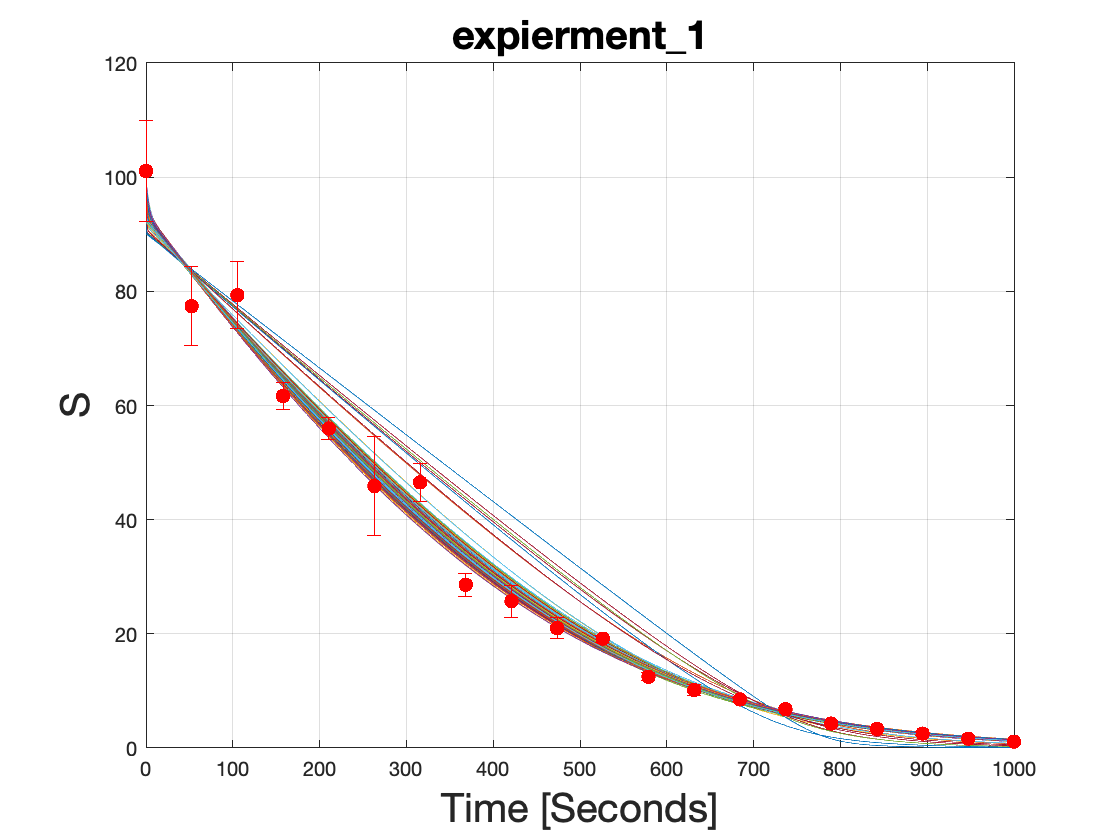

% Plot fits to original experiments
x.converged_start=1;
x.num_samples=1000;
x.plot_auto();

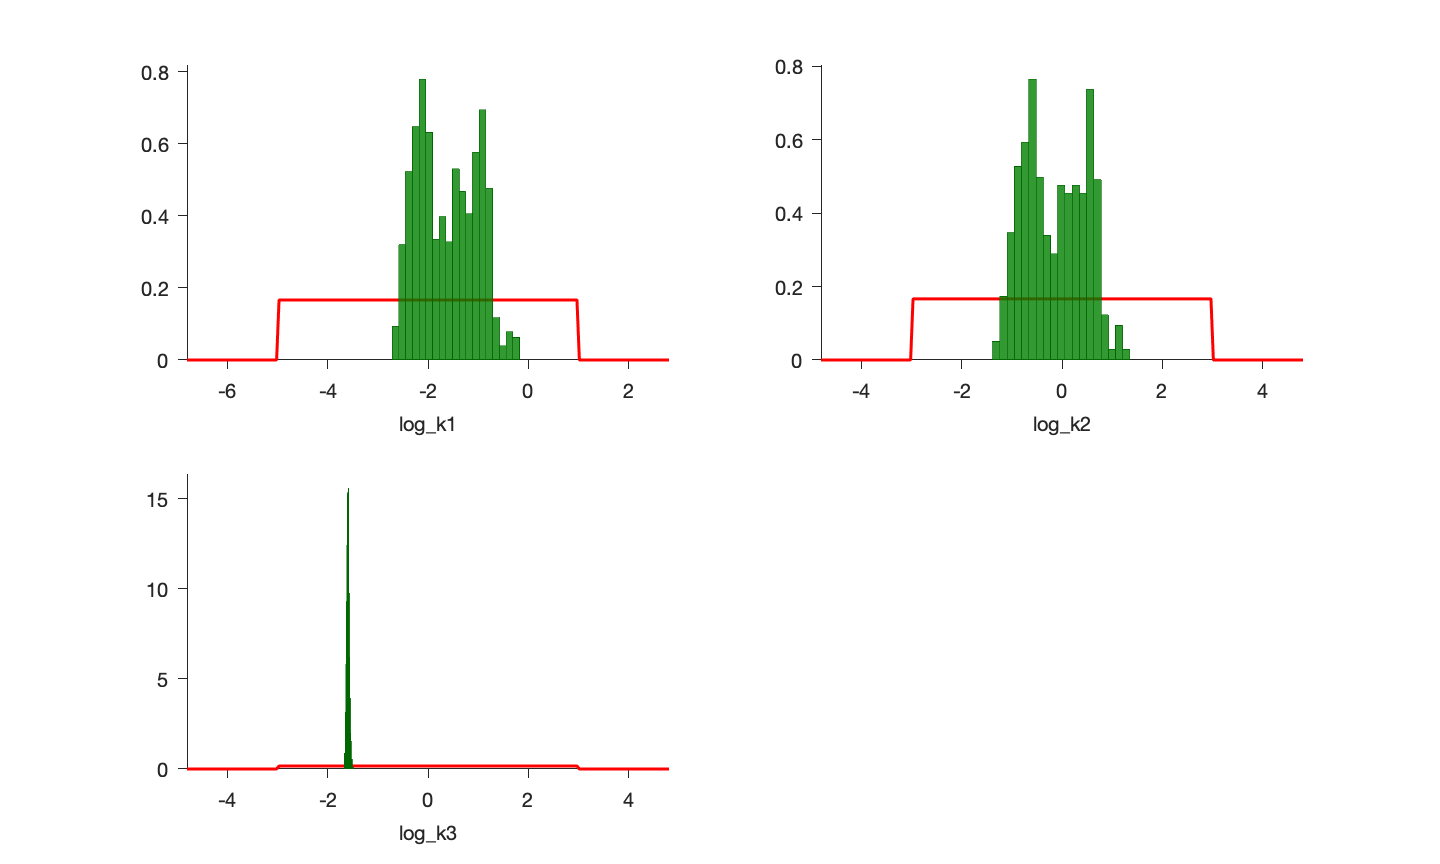

% Plot parameter priors and posterior distributions using ptempest plot_allhists function
iburn = x.converged_start;
samples=squeeze(x.params_chain(1,:,iburn:end));
plot_allhists(samples,x.key_struct);

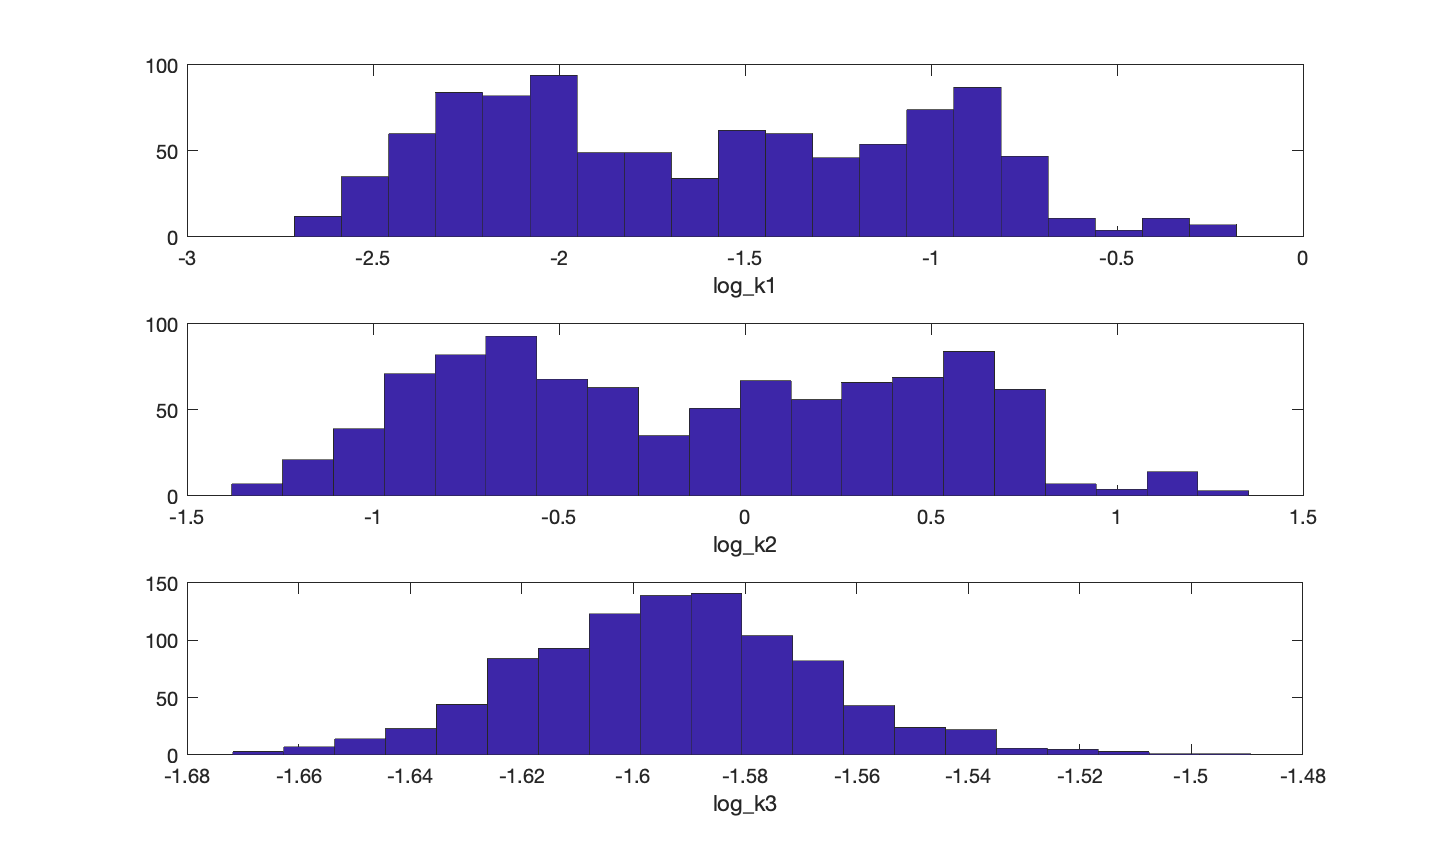

% Alternative histogram plotting method
clf;
iburn = x.converged_start;
offset=3; % use to skip constant parameters. This can be done in a more general way.
samples=squeeze(x.params_chain(1,3:end,iburn:end));
np= size(samples,1);
for i=1:np
  subplot(np,1,i);
  hist(samples(i,:),20);
  xlabel(x.key_struct.param_labels{i+offset-1},"Interpreter","none");
end

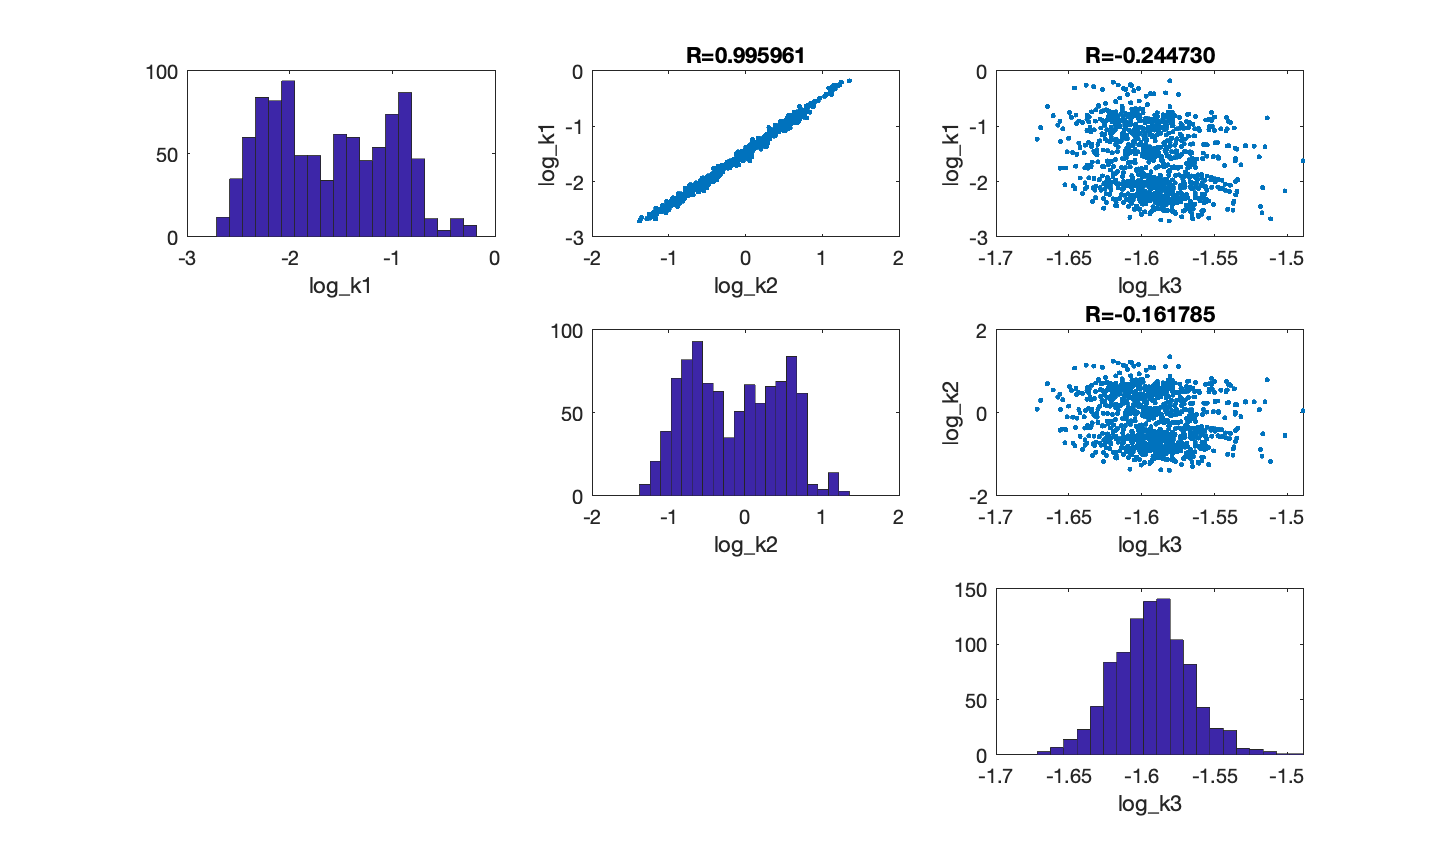

% Display scatterplot of parameter distributions
clf;
iburn = x.converged_start;
offset=3; % use to skip constant parameters. This can be done in a more general way.
samples=squeeze(x.params_chain(1,3:end,iburn:end));
R= corrcoef(samples');
np= size(samples,1);
pos=1;
for i=1:np
    pos=(i-1)*np + i;
    subplot(np,np,pos);
    hist(samples(i,:),20);
    xlabel(x.key_struct.param_labels{i+offset-1},"Interpreter","none");
    pos=pos+1;
    for j=i+1:np
        subplot(np,np,pos);
        plot(samples(j,:),samples(i,:),'.');
        title(sprintf("R=%f",R(i,j)));
        xlabel(x.key_struct.param_labels{j+offset-1},"Interpreter","none");
        ylabel(x.key_struct.param_labels{i+offset-1},"Interpreter","none");
        pos=pos+1;
    end
end